`Erfan Panahi 810198369`

# `Final Project`

`Linear Algebra`

clc
clear
close all

## `Problem 1. `

- `Part a: ``Lagrange Interpolation `

`3rd ``degree polynomial:`

syms X
x = [0, 0.6, 1.03, 1.39];
y = [2.718, 0.797, 0.368, 0.597];
L3 = LagrangeInterpolation(X, x, y)

$$L3 = -0.051593777037439872704355585756122\,X^{3}+2.2238961556603624331643801797806\,X^{2}-4.5174306003294057723917267636628\,X+2.718$$

## `Problem 1. `

- `Part a: ``Lagrange Interpolation `

syms X
x = [0, 1.03, 2.09, 2.29];
y = [2.718, 0.368, 2.718, 2.3];

`3rd ``degree polynomial:`

x = [0, 1.03, 2.09, 2.29];
y = [2.718, 0.368, 2.718, 2.3];
L3 = LagrangeInterpolation(X, x, y)

$$L3 = -2.4325973186914335340355109799583\,X^{3}+9.7421125004099635952327433323921\,X^{2}-9.7351867780807730940159180531435\,X+2.718$$

`4th ``degree polynomial:`

x = [0, 0.6, 1.03, 2.09, 2.29];
y = [2.718, 0.797, 0.368, 2.718, 2.3];
L4 = LagrangeInterpolation(X, x, y)

$$L4 = -1.4444146665555742401408124618013\,X^{4}+5.3816860273742231051262844383868\,X^{3}-3.6873328618904879024764605312057\,X^{2}-2.6146803514110902071558372540134\,X+2.718$$

`5th ``degree polynomial:`

x = [0, 0.6, 1.03, 1.76, 2.09, 2.29];
y = [2.718, 0.797, 0.368, 1.712, 2.718, 2.3];
L5 = LagrangeInterpolation(X, x, y)

$$L5 = -1.775021626308031049903837328417\,X^{5}+9.2234653075556923697812498819851\,X^{4}-16.883297742220564369342499090612\,X^{3}+14.964919216311916739595194518032\,X^{2}-7.8648567129169222652656963616111\,X+2.718$$

`6th ``degree polynomial:`

x = [0, 0.6, 1.03, 1.39, 1.76, 2.09, 2.29];
y = [2.718, 0.797, 0.368, 0.597, 1.712, 2.718, 2.3];
L6 = LagrangeInterpolation(X, x, y)

$$L6 = -0.20212832758571766981566335220832\,X^{6}-0.20448452096700475543613308175838\,X^{5}+4.5500360326135555542063159492413\,X^{4}-10.296998134820143627840251384386\,X^{3}+10.628819505993052424849703743708\,X^{2}-6.8126281321013851929531738298849\,X+2.718$$

- `Definitions: `$f\left(x\right)=e^{\cos \left(3x\right)}$

X = -.1:.01:2.35;
Y = exp(cos(3*X));
L3 = double(subs(L3));
L4 = double(subs(L4));
L5 = double(subs(L5));
L6 = double(subs(L6));

- `Calculating the ``errors``:`

Er3 = (Y - L3).^2;
Er4 = (Y - L4).^2;
Er5 = (Y - L5).^2;
Er6 = (Y - L6).^2;
fprintf('Mean-Squared-Error for each fitted polynomial: \n\t3rd degree: MSE = %f\n\t4th degree: MSE = %f\n\t5th degree: MSE = %f\n\t6th degree: MSE = %f',mean(Er3),mean(Er4),mean(Er5),mean(Er6));

Mean-Squared-Error for each fitted polynomial: 
	3rd degree: MSE = 0.552900
	4th degree: MSE = 0.064066
	5th degree: MSE = 0.064307
	6th degree: MSE = 0.048828

- `Comparing fitted polynomials:`

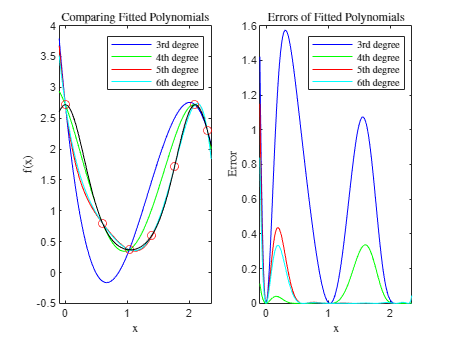

subplot(1,2,1)
plot(X, L3, 'b', X, L4, 'g', X, L5, 'r', X, L6, 'c', x, y, 'ro', X, Y, 'k')
xlabel('x','Interpreter','latex')
ylabel('f(x)','Interpreter','latex')
title('Comparing Fitted Polynomials','Interpreter','latex')
legend('3rd degree','4th degree','5th degree','6th degree','Interpreter','latex')
xlim([-0.1, 2.35])
subplot(1,2,2)
plot(X, Er3, 'b', X, Er4, 'g', X, Er5, 'r', X, Er6, 'c')
xlabel('x','Interpreter','latex')
ylabel('Error','Interpreter','latex')
title('Errors of Fitted Polynomials','Interpreter','latex')
legend('3rd degree','4th degree','5th degree','6th degree','Interpreter','latex')
xlim([-0.1, 2.35])

- `Part b: ``The LU decomposition for the upper hessenberg matrix`

A = [8,2,-4,7,1
     -9,3,0,2,1
     0,4,1,6,-3
     0,0,6,2,7
     0,0,0,4,5]

A =      8     2    -4     7     1
    -9     3     0     2     1
     0     4     1     6    -3
     0     0     6     2     7
     0     0     0     4     5


tic
[L,U] = LU_decomposition(A)

L =     8.0000         0         0         0         0
   -9.0000    5.2500         0         0         0
         0    4.0000    4.4286         0         0
         0         0    6.0000    4.0645         0
         0         0         0    4.0000   -8.0476


U =     1.0000    0.2500   -0.5000    0.8750    0.1250
         0    1.0000   -0.8571    1.8810    0.4048
         0         0    1.0000   -0.3441   -1.0430
         0         0         0    1.0000    3.2619
         0         0         0         0    1.0000


toc

Elapsed time is 0.056639 seconds.


tic
[L,U] = LU_decomposition_UH(A)

L =     8.0000         0         0         0         0
   -9.0000    5.2500         0         0         0
         0    4.0000    4.4286         0         0
         0         0    6.0000    4.0645         0
         0         0         0    4.0000   -8.0476


U =     1.0000    0.2500   -0.5000    0.8750    0.1250
         0    1.0000   -0.8571    1.8810    0.4048
         0         0    1.0000   -0.3441   -1.0430
         0         0         0    1.0000    3.2619
         0         0         0         0    1.0000


toc

Elapsed time is 0.054833 seconds.


function [P] = LagrangeInterpolation(X, x, y)
  n = length(x);
  P = 0;
  for i = 1:n
    Pj = y(i);
    for j = 1:n
      if i ~= j
        Pj = Pj .* ((X-x(j))/(x(i)-x(j))); 
      end
    end
    P = P + Pj;
  end
  P = simplify(vpa(P));
end

function [L, U] = LU_decomposition(A)
    n = size(A,2);
    U = A;
    L = zeros(size(A));
    for i = 1:n
        for j = 1:i-1
            L(i,j) = U(i,j);
            U(i,:) = U(i,:) - U(i,j)*U(j,:);
        end
        L(i,i) = U(i,i);
        U(i,:) = U(i,:) / U(i,i);
    end
end

function [L, U] = LU_decomposition_UH(A)
    n = size(A,2);
    U = A;
    L = zeros(size(A));
    for i = 1:n
        if i>1
            L(i,i-1) = U(i,i-1);
            U(i,:) = U(i,:) - U(i,i-1)*U(i-1,:);
        end
        L(i,i) = U(i,i);
        U(i,:) = U(i,:) / U(i,i);
    end
end